**Task 1**

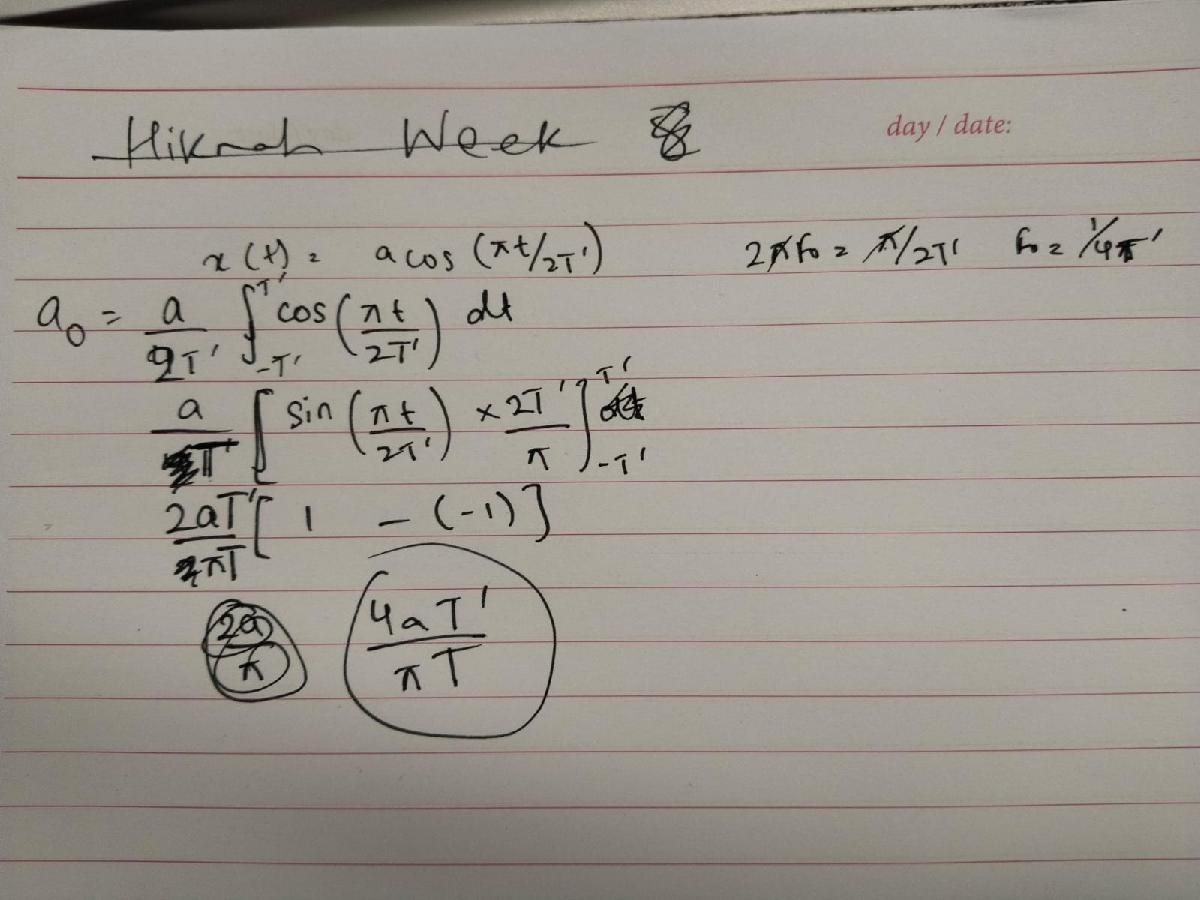

**Task 2**

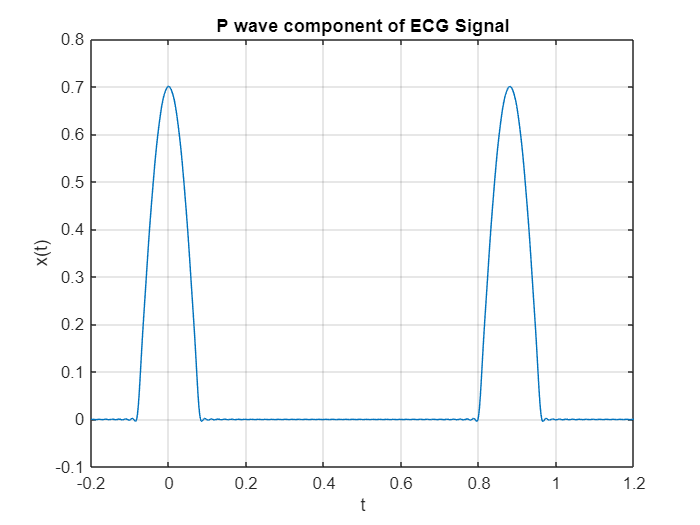

clc;
clear;
close all;

global T;
global N;
global t;
T = 0.88;
N = 50;
t = -0.2: 1/N/10: 1.2;

function x_bar = ECG_Wave_Component(a, T_prime, t0)
    global T;
    global N;
    global t;

    a_0 = 4 * a * T_prime / (pi * T);
    pi_T = pi * T;
    denom = 2 * T;
    coef_factor = 4 * a * T_prime;
    
    x_bar = a_0 * ones(size(t));
    a_n_values = zeros(1, N);
    
    for n = 1:N
        n_term = 2 * n * pi * T_prime;
        diff_term = pi_T - n_term;
        sum_term = pi_T + n_term;
        sin_diff = sin(diff_term/denom);
        sin_sum = sin(sum_term/denom);
        ratio_diff = sin_diff / diff_term;
        ratio_sum = sin_sum / sum_term;
    
        a_n_values(n) = coef_factor * (ratio_diff + ratio_sum);
        x_bar = x_bar + a_n_values(n) * cos(2 * pi * n * (t-t0)/T);
    end
end

P_Wave = ECG_Wave_Component(0.35, 0.16, 0);


figure;
plot(t, P_Wave);
title('P wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');
grid on;

**Task 3)**

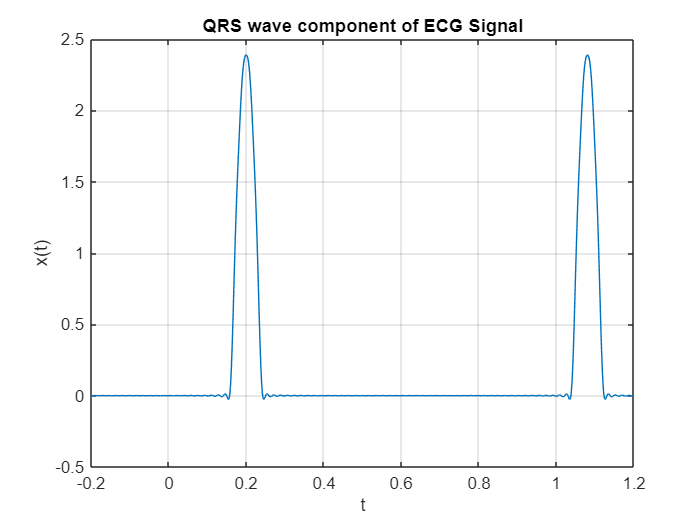

QRS_Wave = ECG_Wave_Component(1.2, 0.08, 0.2);
figure;
plot(t, QRS_Wave);
title('QRS wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');
grid on;

**Task 4**

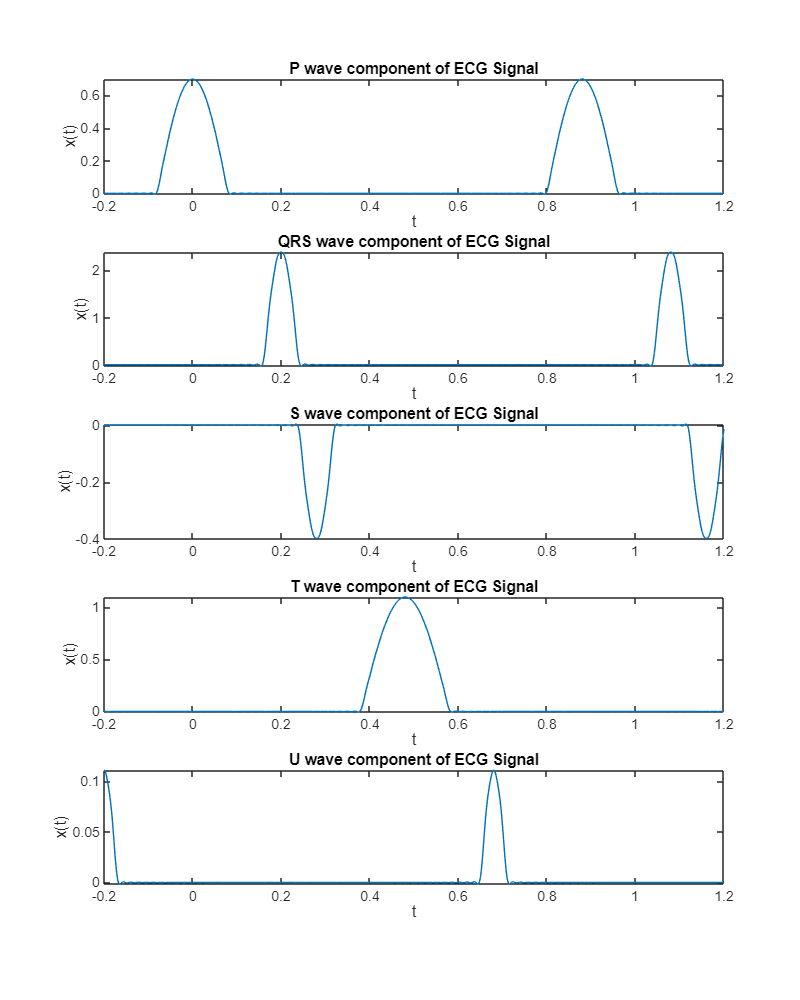

S_Wave = ECG_Wave_Component(-0.2, 0.08, 0.28);
T_Wave = ECG_Wave_Component(0.55, 0.2, 0.48);
U_Wave = ECG_Wave_Component(0.055, 0.06, 0.68);

figure('Position', [100, 100, 800, 1000]);
subplot 511;
plot(t, P_Wave);
title('P wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');

subplot 512;
plot(t, QRS_Wave);
title('QRS wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');

subplot 513;
plot(t, S_Wave);
title('S wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');

subplot 514;
plot(t, T_Wave);
title('T wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');

subplot 515;
plot(t, U_Wave);
title('U wave component of ECG Signal');
xlabel('t');
ylabel('x(t)');

**Task 5**

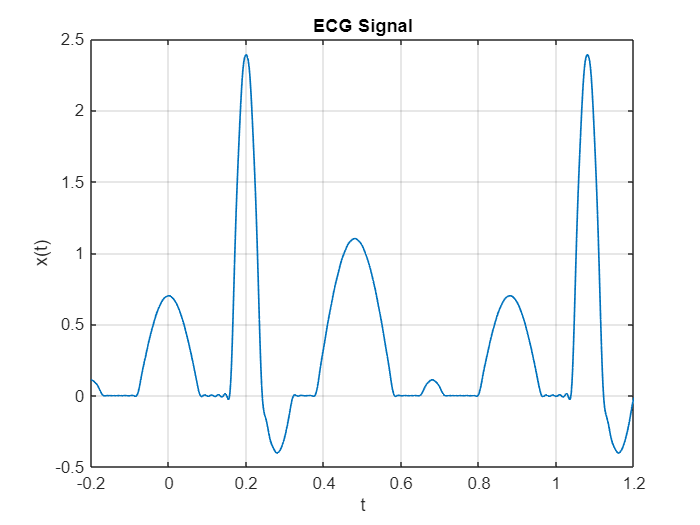

ECG = P_Wave + QRS_Wave + S_Wave + T_Wave + U_Wave;
figure; 
plot(t,ECG, 'linewidth',1);
title('ECG Signal');
xlabel('t');
ylabel('x(t)');
grid on;